clear; close all;

[ProgressClassFile, ProgressClassFolder, tf] = uigetfile("F:\YuLab\Work\GPS\Data\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);

FigFolder = fullfile(ProgressClassFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end

Params = [
    "dMedian"
    "dIQR"
    "dMode"
    ];

Func = {
    @(x) median(x, 'omitnan');
    @iqr;
    @calMode;
    };

FP = obj.MixedFP;

theta = strings(length(Params)*2, 1);
port = strings(length(Params)*2, 1);
theta_hat = zeros(length(Params)*2, 1);
ci_95 = zeros(length(Params)*2, 2);

n_boot = 1000;
alpha_ci = 0.05;

for i = 1:length(Params) 
    cued_this = find(obj.CueUncue==0);
    for p = 1:length(obj.Ports)
        ind = 2*i+p-2;
        theta(ind) = Params(i);
        port(ind) = obj.Ports(p);

        data_control = obj.HDSortedControl{cued_this, p};
        data_chemo = obj.HDSortedChemo{cued_this, p};
        dParam_hat = Func{i}(data_chemo) - Func{i}(data_control);

        param_control_boot = bootstrp(n_boot, Func{i}, data_control);
        param_chemo_boot = bootstrp(n_boot, Func{i}, data_chemo);
        dParam_boot = param_chemo_boot - param_control_boot;
        dParam_boot_ci = [2*dParam_hat-quantile(dParam_boot, 1-alpha_ci/2) 2*dParam_hat-quantile(dParam_boot, alpha_ci/2)];

        theta_hat(ind) = dParam_hat;
        ci_95(ind, :) = dParam_boot_ci;
    end
end

StatTableHD = table(theta, port, theta_hat, ci_95);
head(StatTableHD)

ans = 6×4 table
      theta      port    theta_hat            ci_95         
    _________    ____    _________    ______________________
    "dMedian"    "L"       -0.0723     -0.10318     -0.03205
    "dMedian"    "R"        -0.049      -0.0896      -0.0109
    "dIQR"       "L"       0.72665      0.67466       1.0488
    "dIQR"       "R"       0.73535      0.66684        1.315
    "dMode"      "L"     -0.020873     -0.11611    0.0042518
    "dMode"      "R"     0.0011008    -0.070853     0.064071

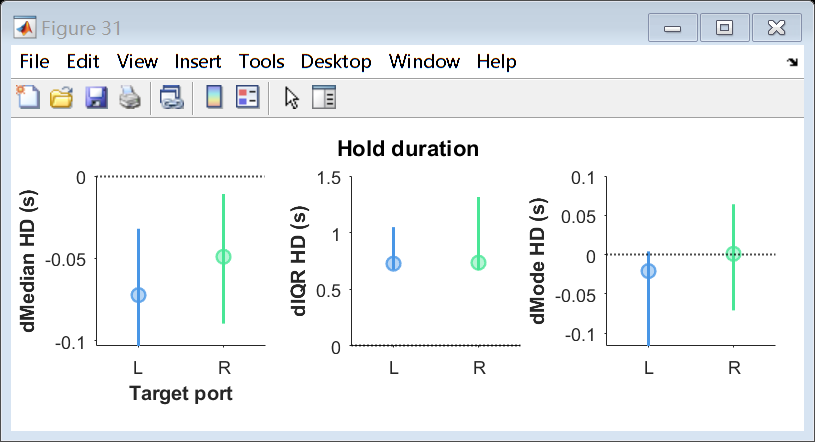

fig = figure(31); clf(31);
set(fig, 'Visible', 'on', 'Units', 'Centimeters', 'Position', [1 1 14 5.5], 'PaperPositionMode', 'Auto', 'Color', 'w');

set_fig_title(fig, 'Hold duration', 'FontSize', 11);

x_pos = 1.5; y_pos = 1.5;
ax_size = [3 3];
for i = 1:length(Params) 

    ind = (1:2) + (i-1)*2;

    ax = axes();
    set(ax, 'Parent', fig, 'Units', 'Centimeters', 'Position', [x_pos, y_pos ax_size], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');
    
    yline(ax, 0, 'LineWidth', 1, 'LineStyle', ':', 'Color', 'k');
    for p = 1:length(obj.Ports)
        scatter(ax, p, StatTableHD.theta_hat(ind(p)), 48, 'Marker', 'o', 'LineWidth', 1.2, ...
            'MarkerEdgeColor', GPSColor.("Port"+obj.Ports(p)), 'MarkerEdgeAlpha', 0.8, ...
            'MarkerFaceColor', GPSColor.("Port"+obj.Ports(p)), 'MarkerFaceAlpha', 0.4);
        plot(ax, [p p], StatTableHD.ci_95(ind(p), :), ...
            'Color', GPSColor.("Port"+obj.Ports(p)), 'LineWidth', 1.5);
    end
    set(ax, 'XLim', [.5 2.5], 'XTick', [1 2], 'XTickLabel', ["L", "R"]);
    ax.YLabel.String = Params(i) + " HD (s)";
    ax.YLabel.FontWeight = "bold";
    if i==1
        ax.XLabel.String = "Target port";
        ax.XLabel.FontWeight = "bold";
    end

    x_pos = x_pos + ax.Position(3) + 1.5;
end
fig_name = "BootTest_HD_" + obj.Subject + "_" + obj.Task + ".png";
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig, fig_path, 'Resolution', 600);


theta = strings(length(Params)*2, 1);
port = strings(length(Params)*2, 1);
theta_hat = zeros(length(Params)*2, 1);
ci_95 = zeros(length(Params)*2, 2);

for i = 1:length(Params) 
    
    n_boot = 1000;
    alpha_ci = 0.05;
    band_width = 0.12;

    cued_this = find(obj.CueUncue==0);

    for p = 1:length(obj.Ports)

        ind = 2*i+p-2;
        theta(ind) = Params(i);
        port(ind) = obj.Ports(p);

        data_control = obj.MTSortedControl{cued_this, p};
        data_chemo = obj.MTSortedChemo{cued_this, p};
        dParam_hat = Func{i}(data_chemo) - Func{i}(data_control);

        param_control_boot = bootstrp(n_boot, Func{i}, data_control);
        param_chemo_boot = bootstrp(n_boot, Func{i}, data_chemo);
        dParam_boot = param_chemo_boot - param_control_boot;
        dParam_boot_ci = [2*dParam_hat-quantile(dParam_boot, 1-alpha_ci/2) 2*dParam_hat-quantile(dParam_boot, alpha_ci/2)];

        theta_hat(ind) = dParam_hat;
        ci_95(ind, :) = dParam_boot_ci;
    end
    
end

StatTableMT = table(theta, port, theta_hat, ci_95);
head(StatTableMT)

ans = 6×4 table
      theta      port    theta_hat            ci_95        
    _________    ____    _________    _____________________
    "dMedian"    "L"       -0.0217     -0.0598       0.0023
    "dMedian"    "R"        0.0536      0.0283       0.0697
    "dIQR"       "L"     -0.065575     -0.1235    -0.017325
    "dIQR"       "R"        0.0696      0.0379      0.11911
    "dMode"      "L"     -0.092904    -0.12501    -0.085737
    "dMode"      "R"      0.053733    0.033803      0.11538

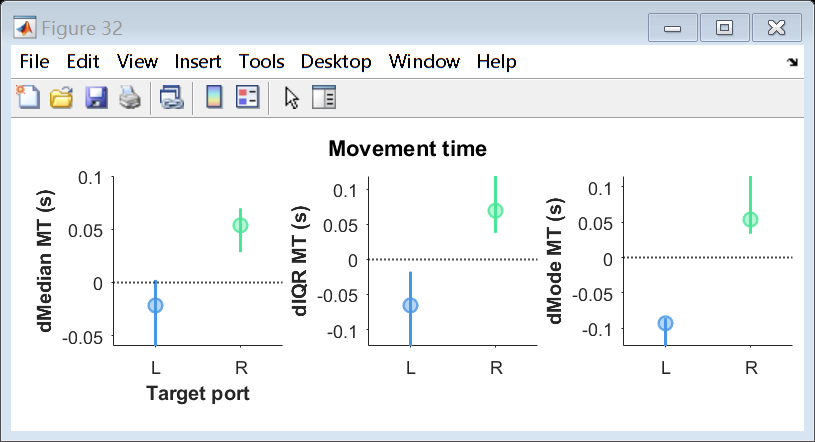

fig = figure(32); clf(32);
set(fig, 'Visible', 'on', 'Units', 'Centimeters', 'Position', [1 1 14 5.5], 'PaperPositionMode', 'Auto', 'Color', 'w');

set_fig_title(fig, 'Movement time', 'FontSize', 11);

x_pos = 1.8; y_pos = 1.5;
ax_size = [3 3];
for i = 1:length(Params) 

    ind = (1:2) + (i-1)*2;

    ax = axes();
    set(ax, 'Parent', fig, 'Units', 'Centimeters', 'Position', [x_pos, y_pos ax_size], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');
    
    yline(ax, 0, 'LineWidth', 1, 'LineStyle', ':', 'Color', 'k');
    for p = 1:length(obj.Ports)
        scatter(ax, p, StatTableMT.theta_hat(ind(p)), 48, 'Marker', 'o', 'LineWidth', 1.2, ...
            'MarkerEdgeColor', GPSColor.("Port"+obj.Ports(p)), 'MarkerEdgeAlpha', 0.8, ...
            'MarkerFaceColor', GPSColor.("Port"+obj.Ports(p)), 'MarkerFaceAlpha', 0.4);
        plot(ax, [p p], StatTableMT.ci_95(ind(p), :), ...
            'Color', GPSColor.("Port"+obj.Ports(p)), 'LineWidth', 1.5);
    end
    set(ax, 'XLim', [.5 2.5], 'XTick', [1 2], 'XTickLabel', ["L", "R"]);
    ax.YLabel.String = Params(i) + " MT (s)";
    ax.YLabel.FontWeight = "bold";
    if i==1
        ax.XLabel.String = "Target port";
        ax.XLabel.FontWeight = "bold";
    end

    x_pos = x_pos + ax.Position(3) + 1.5;

    drawnow;
end

fig_name = "BootTest_MT_" + obj.Subject + "_" + obj.Task + ".png";
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig, fig_path, 'Resolution', 600);

theta = strings(length(Params)*2, 1);
port = strings(length(Params)*2, 1);
theta_hat = zeros(length(Params)*2, 1);
ci_95 = zeros(length(Params)*2, 2);

for i = 1:length(Params) 
    
    n_boot = 1000;
    alpha_ci = 0.05;
    band_width = 0.12;

    cued_this = find(obj.CueUncue==0);

    for p = 1:length(obj.Ports)

        ind = 2*i+p-2;
        theta(ind) = Params(i);
        port(ind) = obj.Ports(p);

        data_control = obj.HDSortedControl{cued_this, p};
        data_control = data_control(data_control>0.5);
        data_chemo = obj.HDSortedChemo{cued_this, p};
        data_chemo = data_chemo(data_chemo>0.5);
        dParam_hat = Func{i}(data_chemo) - Func{i}(data_control);

        param_control_boot = bootstrp(n_boot, Func{i}, data_control);
        param_chemo_boot = bootstrp(n_boot, Func{i}, data_chemo);
        dParam_boot = param_chemo_boot - param_control_boot;
        dParam_boot_ci = [2*dParam_hat-quantile(dParam_boot, 1-alpha_ci/2) 2*dParam_hat-quantile(dParam_boot, alpha_ci/2)];

        theta_hat(ind) = dParam_hat;
        ci_95(ind, :) = dParam_boot_ci;
    end
    
end

StatTableHDvalid = table(theta, port, theta_hat, ci_95);
head(StatTableHDvalid)

ans = 6×4 table
      theta      port    theta_hat            ci_95         
    _________    ____    _________    ______________________
    "dMedian"    "L"      -0.00695      -0.0454     0.023525
    "dMedian"    "R"        0.0308    -0.009475     0.066825
    "dIQR"       "L"      0.091125     0.055175      0.12756
    "dIQR"       "R"       0.11287     0.082225      0.15814
    "dMode"      "L"     -0.015341     -0.13844     0.042534
    "dMode"      "R"      0.028608    -0.044962      0.15897

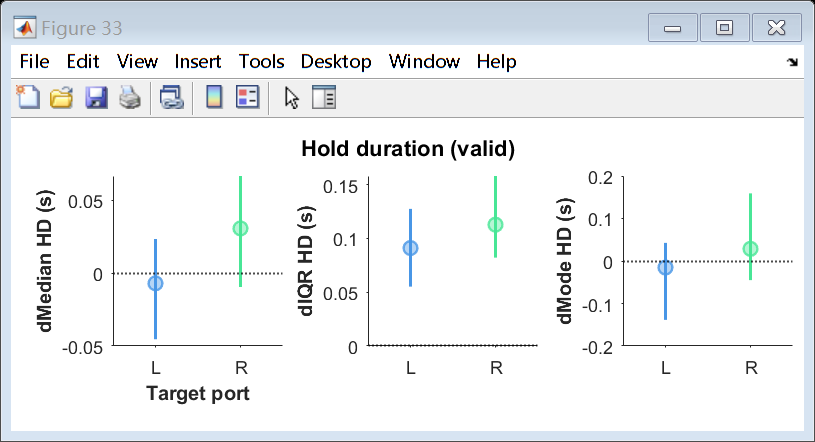

fig = figure(33); clf(33);
set(fig, 'Visible', 'on', 'Units', 'Centimeters', 'Position', [1 1 14 5.5], 'PaperPositionMode', 'Auto', 'Color', 'w');

set_fig_title(fig, 'Hold duration (valid)', 'FontSize', 11);

x_pos = 1.8; y_pos = 1.5;
ax_size = [3 3];
for i = 1:length(Params) 

    ind = (1:2) + (i-1)*2;

    ax = axes();
    set(ax, 'Parent', fig, 'Units', 'Centimeters', 'Position', [x_pos, y_pos ax_size], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'Color', 'none');
    
    yline(ax, 0, 'LineWidth', 1, 'LineStyle', ':', 'Color', 'k');
    for p = 1:length(obj.Ports)
        scatter(ax, p, StatTableHDvalid.theta_hat(ind(p)), 48, 'Marker', 'o', 'LineWidth', 1.2, ...
            'MarkerEdgeColor', GPSColor.("Port"+obj.Ports(p)), 'MarkerEdgeAlpha', 0.8, ...
            'MarkerFaceColor', GPSColor.("Port"+obj.Ports(p)), 'MarkerFaceAlpha', 0.4);
        plot(ax, [p p], StatTableHDvalid.ci_95(ind(p), :), ...
            'Color', GPSColor.("Port"+obj.Ports(p)), 'LineWidth', 1.5);
    end
    set(ax, 'XLim', [.5 2.5], 'XTick', [1 2], 'XTickLabel', ["L", "R"]);
    ax.YLabel.String = Params(i) + " HD (s)";
    ax.YLabel.FontWeight = "bold";
    if i==1
        ax.XLabel.String = "Target port";
        ax.XLabel.FontWeight = "bold";
    end

    x_pos = x_pos + ax.Position(3) + 1.5;

    drawnow;
end

fig_name = "BootTest_HD_valid_" + obj.Subject + "_" + obj.Task + ".png";
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig, fig_path, 'Resolution', 600);

data_control = cell(1, 2);
data_chemo = cell(1, 2);
pdf_control = cell(1, 2);
pdf_chemo = cell(1, 2);
pdf_control_ci = cell(1, 2);
pdf_chemo_ci = cell(1, 2);

cdf_control = cell(1, 2);
cdf_chemo = cell(1, 2);
cdf_control_ci = cell(1, 2);
cdf_chemo_ci = cell(1, 2);

bins = 0:0.001:3;
band_width = 0.1;
n_boot = 1000;
valid = 0;

kde_pdf = @(x) ksdensity(x, bins, 'Function', 'pdf', 'Bandwidth', band_width);
kde_cdf = @(x) ksdensity(x, bins, 'Function', 'cdf', 'Bandwidth', band_width);

for p = 1:2
    data_control{p} = obj.HDSortedControl{cued_this, p};
    data_chemo{p} = obj.HDSortedChemo{cued_this, p};
    switch valid
        case 1
            data_control{p} = data_control{p}(data_control{p}>0.5);
            data_chemo{p} = data_chemo{p}(data_chemo{p}>0.5);
    end

    disp([p 1]);
    pdf_control{p} = kde_pdf(data_control{p});
    pdf_chemo{p} = kde_pdf(data_chemo{p});
    pdf_control_ci{p} = bootci(n_boot, {kde_pdf, data_control{p}}, 'type', 'cper');
    pdf_chemo_ci{p} = bootci(n_boot, {kde_pdf, data_chemo{p}}, 'type', 'cper');

    disp([p 2]);
    cdf_control{p} = kde_cdf(data_control{p});
    cdf_chemo{p} = kde_cdf(data_chemo{p});
    cdf_control_ci{p} = bootci(n_boot, {kde_cdf, data_control{p}}, 'type', 'cper');
    cdf_chemo_ci{p} = bootci(n_boot, {kde_cdf, data_chemo{p}}, 'type', 'cper');
end

     1     1


     1     2


     2     1


     2     2


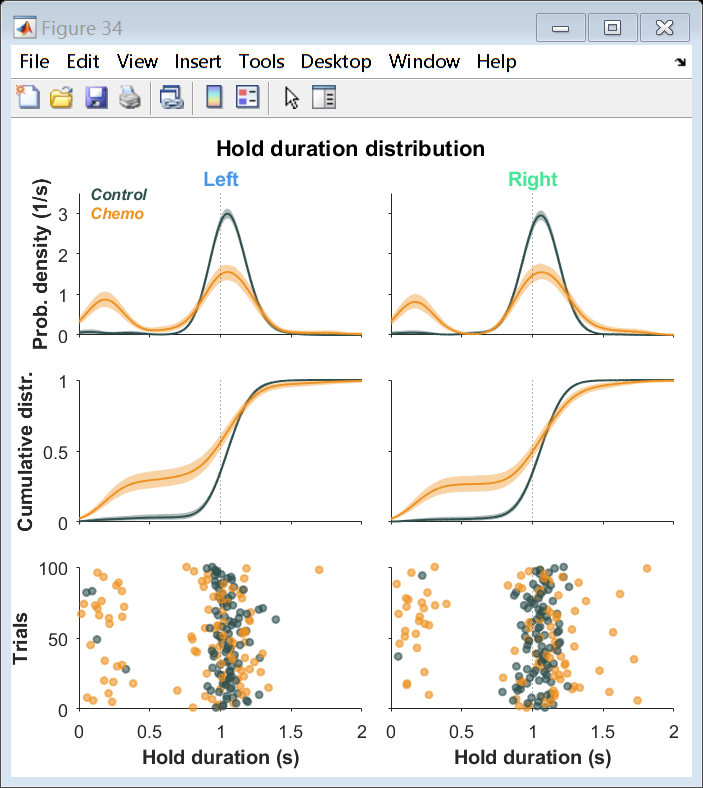


fig = figure(34); clf(34);
set(fig, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 12 11.6], 'Color', 'w');

set_fig_title(fig, 'Hold duration distribution', 'FontSize', 11);

ax = cell(3,2);

for p = 1:2
ax{1,p} = axes(fig, 'Units', 'centimeters', 'Position', [1.2+(p-1)*5.5 7.8 5 2.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax{1,p}, FP, 'LineWidth', .5, 'LineStyle', ':');
fill(ax{1,p}, [bins flip(bins)], [pdf_control_ci{p}(1,:) flip(pdf_control_ci{p}(2,:))], 'y', ...
    'FaceColor', GPSColor.Control, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
p1 = plot(ax{1,p}, bins, pdf_control{p}, ...
    'color', GPSColor.Control, 'linewidth', 1, 'LineStyle', '-');
fill(ax{1,p}, [bins flip(bins)], [pdf_chemo_ci{p}(1,:) flip(pdf_chemo_ci{p}(2,:))], 'y', ...
    'FaceColor', GPSColor.Treat, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
p2 = plot(ax{1,p}, bins, pdf_chemo{p}, ...
    'color', GPSColor.Treat  , 'linewidth', 1, 'LineStyle', '-');

ax{2,p} = axes(fig, 'Units', 'centimeters', 'Position', [1.2+(p-1)*5.5 4.5 5 2.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax{2,p}, FP, 'LineWidth', .5, 'LineStyle', ':');
fill(ax{2,p}, [bins flip(bins)], [cdf_control_ci{p}(1,:) flip(cdf_control_ci{p}(2,:))], 'y', ...
    'FaceColor', GPSColor.Control, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
plot(ax{2,p}, bins, cdf_control{p}, ...
    'color', GPSColor.Control, 'linewidth', 1, 'LineStyle', '-');
fill(ax{2,p}, [bins flip(bins)], [cdf_chemo_ci{p}(1,:) flip(cdf_chemo_ci{p}(2,:))], 'y', ...
    'FaceColor', GPSColor.Treat, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
plot(ax{2,p}, bins, cdf_chemo{p}, ...
    'color', GPSColor.Treat  , 'linewidth', 1, 'LineStyle', '-');

ax{3,p} = axes(fig, 'Units', 'centimeters', 'Position', [1.2+(p-1)*5.5 1.2 5 2.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax{3,p}, FP, 'LineWidth', .5, 'LineStyle', ':');

hd_this_control = data_control{p}(randperm(length(data_control{p}), 100));
hd_this_chemo = data_chemo{p}(randperm(length(data_chemo{p}), 100));
hd_this = [hd_this_control; hd_this_chemo];
c_this = [repmat(GPSColor.Control, 100, 1); repmat(GPSColor.Treat, 100, 1)];
t_this = [1:100 1:100]';

id_perm = randperm(200);
hd_perm = hd_this(id_perm);
c_perm = c_this(id_perm, :);
t_perm = t_this(id_perm);

scatter(ax{3,p}, hd_perm, t_perm, 12, c_perm, ...
    'MarkerEdgeColor', 'flat', 'MarkerEdgeAlpha', 0.6, 'LineWidth', 1, ...
    'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', 0.6);

for a = 1:3
    set(ax{a,p}, 'XLim', FP + [-1 1]);

    if p==2
        ax{a,p}.YTickLabel = [];
    end
    if a<3
        ax{a,p}.XTickLabel = [];
    else
        ax{a,p}.XLabel.String = "Hold duration (s)";
        ax{a,p}.XLabel.FontWeight = "bold";
    end
end

end

%
ax_legend = axes(fig, 'Units', 'centimeters', 'Position', [ax{1,1}.Position(1)+.2 ax{1,1}.Position(2)+ax{1,1}.Position(4)-1 2 1], ...
    'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'XColor', 'none', 'YColor', 'none', 'Color', 'none', 'YDir', 'reverse');
text(ax_legend, 0, 0, '\it{Control}', 'FontSize', 8, 'FontWeight', 'bold', 'Color', GPSColor.Control);
text(ax_legend, 0, 1, '\it{Chemo}', 'FontSize', 8, 'FontWeight', 'bold', 'Color', GPSColor.Treat);
set(ax_legend, 'XLim', [0 1], 'YLim', [0 3]);

%
ax{1,1}.YLim(2) = max([ax{1,1}.YLim(2) ax{1,2}.YLim(2)]);
ax{1,1}.YLim(2) = .5 * (ceil(ax{1,1}.YLim(2)) + round(ax{1,1}.YLim(2)));
ax{1,2}.YLim(2) = ax{1,1}.YLim(2);

%
ax{1,1}.YLabel.String = "Prob. density (1/s)";
ax{1,1}.YLabel.FontWeight = "bold";

ax{2,1}.YLabel.String = "Cumulative distr.";
ax{2,1}.YLabel.FontWeight = "bold";

ax{3,1}.YLabel.String = "Trials";
ax{3,1}.YLabel.FontWeight = "bold";

%
ax{1,1}.Title.String = "Left";
ax{1,1}.Title.Color = GPSColor.PortL;
ax{1,1}.Title.FontWeight = "bold";

ax{1,2}.Title.String = "Right";
ax{1,2}.Title.Color = GPSColor.PortR;
ax{1,2}.Title.FontWeight = "bold";

switch valid
    case 0
        fig_name = sprintf("Test_%s_Distr_Timing_%s.jpg", obj.Task, obj.Subject);
    case 1
        fig_name = sprintf("Test_%s_Distr_Timing_valid_%s.jpg", obj.Task, obj.Subject);
end
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig, fig_path, 'Resolution', 600);

function mode_this = calMode(x)

    [x_pdf, xi] = ksdensity(x);
    [~, id] = max(x_pdf);
    mode_this = xi(id);

end

function p_val = PermTest(x, y, varargin)

% parsing input
P = inputParser;

addRequired(P, 'x', @isvector);
addRequired(P, 'y', @isvector);

addParameter(P, 'n_perm', 1000, @isnumeric);
addParameter(P, 'func' , @(x) mean(x, 'omitnan'), @(x) isa(x, 'function_handle'));
addParameter(P, 'sided', 'both', @(x) ismember(x, {'both', 'smaller', 'larger'}));

parse(P, x, y, varargin{:})

x = P.Results.x;
y = P.Results.y;
n_perm = P.Results.n_perm;
func = P.Results.func;
sided = P.Results.sided;

%
x = x(:);
y = y(:);
d = [x; y];

n_x = length(x);
n_y = length(y);
n_d = n_x + n_y;

param_x_hat = func(x);
param_y_hat = func(y);

d_param_hat = param_x_hat - param_y_hat;
d_param_perm = zeros(1, n_perm);

for i = 1:n_perm
    d_i = d(randperm(n_d));
    x_i = d_i(1:n_x);
    y_i = d_i(n_x+1:end);

    param_xi_hat = func(x_i);
    param_yi_hat = func(y_i);
    d_param_perm(i) = param_xi_hat - param_yi_hat;
end

switch sided
    case {'both'}
        p_val = (sum(abs(d_param_perm) > abs(d_param_hat)) + 1) / n_perm;
    case {'smaller'}
        p_val = (sum(d_param_perm < d_param_hat) + 1) / n_perm;
    case {'larger'}
        p_val = (sum(d_param_perm > d_param_hat) + 1) / n_perm;
end

end